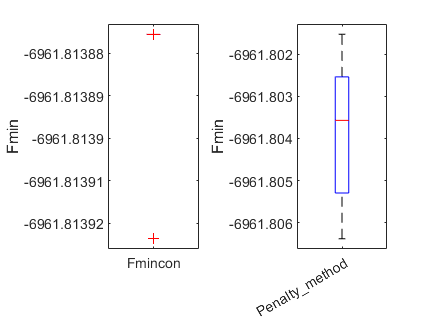

%优化结果对比
figure
subplot(1,2,1);
boxplot(result_fmin_f(:,3),'Labels',{'Fmincon'});
ylabel("Fmin");
subplot(1,2,2);
boxplot(result_fmin_p(:,3),"Labels",{'Penalty_method'});
ylabel('Fmin');

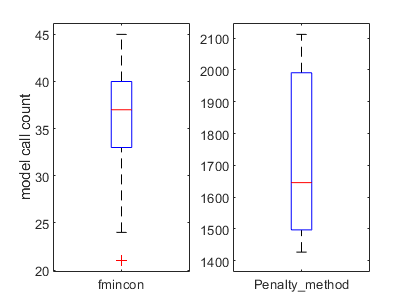


%模型调用次数
figure
subplot(1,2,1);
boxplot(result_fmin_f(:,4),"Labels",{'fmincon'});
ylabel('model call count');
subplot(1,2,2);
boxplot(result_fmin_p(:,4),"Labels",{'Penalty_method'});

data=[result_fmin_f(:,3:4),result_fmin_p(:,3:4)];
data_process=[min(data);mean(data);max(data);median(data)];